clear all
load TR4_data.mat
Q=sym("q",[1 3]);
L=sym("l",[1 4]);
J=TR4_jacobian(Q,link);
detJ=det(J)

assume(Q,'positive')
simplify(detJ)

$$ans = \frac{15\,\sqrt{2}\,\cos\left(q_{1}\right)\,\cos\left(q_{3}\right)}{2}-\frac{25\,\sqrt{2}\,\sin\left(q_{1}\right)}{2}-\frac{25\,\sqrt{2}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)}{2}-\frac{25\,\sqrt{2}\,\cos\left(q_{1}\right)}{2}+\frac{25\,\sqrt{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)}{2}-\frac{15\,\sqrt{2}\,\cos\left(q_{1}\right)\,\sin\left(q_{3}\right)}{2}+\frac{15\,\sqrt{2}\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)}{2}-\frac{15\,\sqrt{2}\,\sin\left(q_{1}\right)\,\sin\left(q_{3}\right)}{2}+25\,\sqrt{2}\,\cos\left(q_{1}\right)\,{\cos\left(q_{3}\right)}^{2}+25\,\sqrt{2}\,{\cos\left(q_{3}\right)}^{2}\,\sin\left(q_{1}\right)-\frac{15\,\sqrt{2}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)}{2}-\frac{15\,\sqrt{2}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)}{2}+\frac{15\,\sqrt{2}\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)}{2}+\frac{15\,\sqrt{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{3}\right)}{2}-25\,\sqrt{2}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{3}\right)+25\,\sqrt{2}\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{3}\right)$$

detJ=matlabFunction(detJ);



## calcolo singolarità

load TR4_data.mat
Sol=[];
point=[];
Q=[];
for q1 =0:pi/4:2*pi
    for q2 = 0:pi/4:2*pi
        for q3 = 0:pi/4:2*pi
            q=[q1,q2,q3];
            sol=abs(detJ(q1,q2,q3));
            Sol=[Sol sol];
            Q=[Q q'];
        end
    end
end
save Punti_singolarita point Sol

## Ricerca singolarità

load Punti_singolarita.mat
load Absolute_Solution
close all
sing=[];
Q_=[];
media=mean(Sol);
for i=1:length(Sol)
    el=Sol(i);
    if el<eps
        sing=[sing el];
        Q_=[Q_ Q(:,i)];
     end
end


## print data

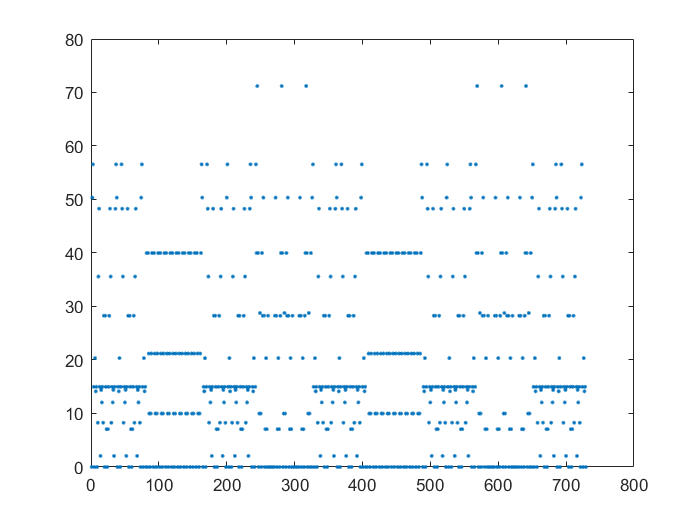

close all
plot(Sol,'.')

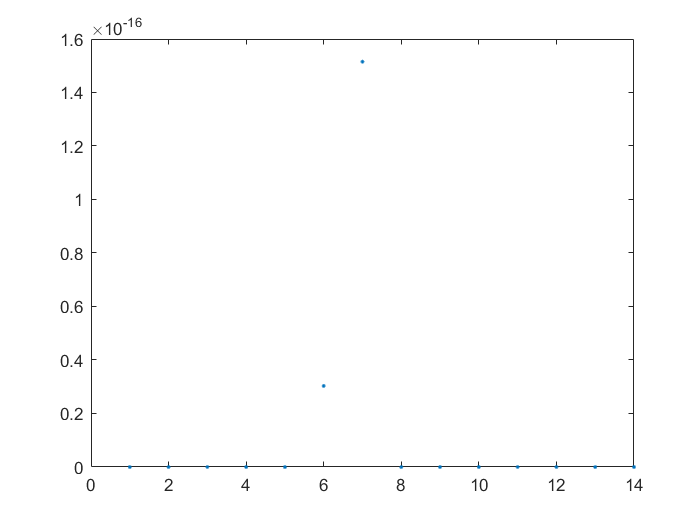

plot(sing,'.')

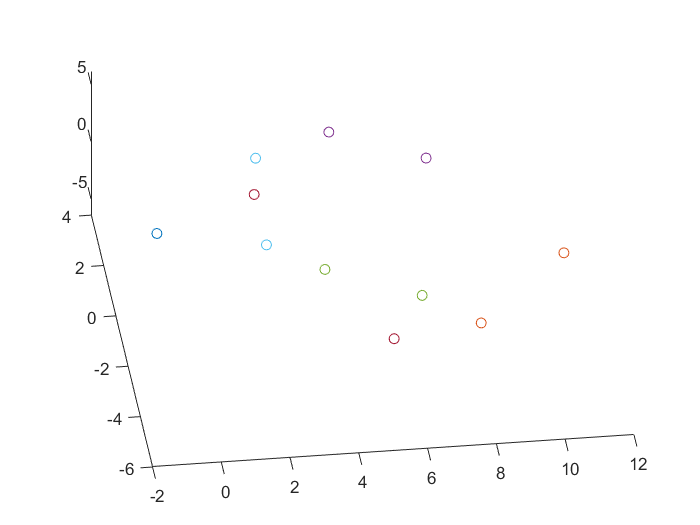

for i=1:length(sing)
    figure(1)
    point=TR4_dirKin(Q_(:,i)',link);
    plot3(point(1),point(2),point(3),'o')
    hold on
    %TR4_plot(Q_(:,i)',link,'b',1)
    
end

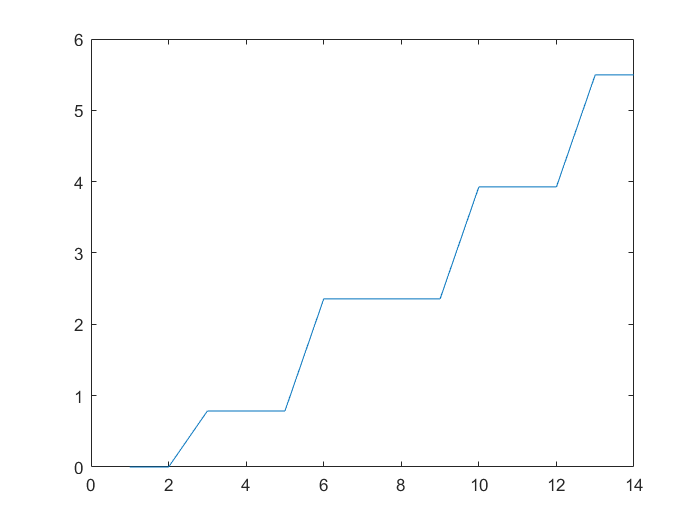

figure
plot(Q_(1,:))

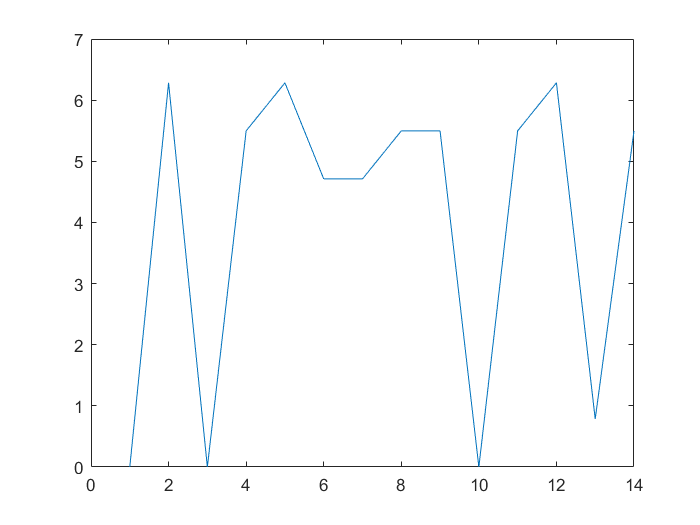

plot(Q_(2,:))

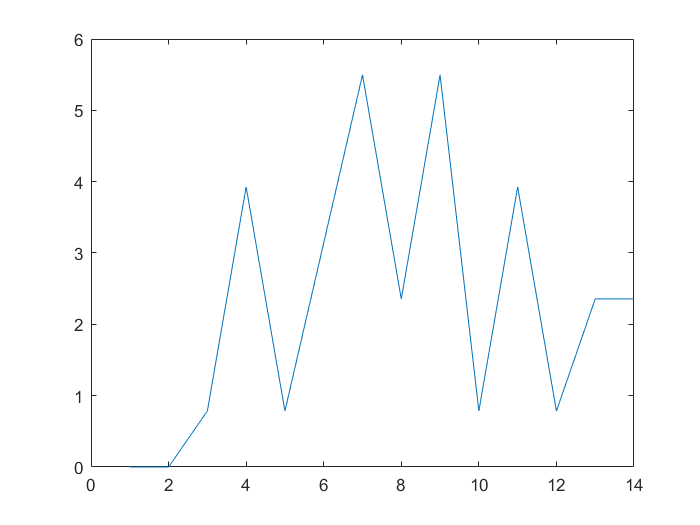

plot(Q_(3,:))

## prova genetic algorithm

close all
opt=optimoptions('ga',"FunctionTolerance",10^-9,"ConstraintTolerance",10^-6)

opt =   ga options:

   Set properties:
             ConstraintTolerance: 1.0000e-06
               FunctionTolerance: 1.0000e-09

   Default properties:
                     CreationFcn: @gacreationuniform
                    CrossoverFcn: @crossoverscattered
               CrossoverFraction: 0.8000
                         Display: 'final'
                      EliteCount: '0.05*PopulationSize'
                    FitnessLimit: -Inf
               FitnessScalingFcn: @fitscalingrank
                       HybridFcn: []
         InitialPopulationMatrix: []
          InitialPopulationRange: []
             InitialScoresMatrix: []
                  MaxGenerations: '100*numberOfVariables'
             MaxStallGenerations: 50
                    MaxStallTime: Inf
                         MaxTime: Inf
                     MutationFcn: {@mutationgaussian  [1]  [1]}
    NonlinearConstraintAlgorithm: 

[x,fval,flag]=ga(@detJacobian,3,opt)

Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


x =   -20.0553   -2.8703    2.7900


fval = 1.1168e-04

flag = 1

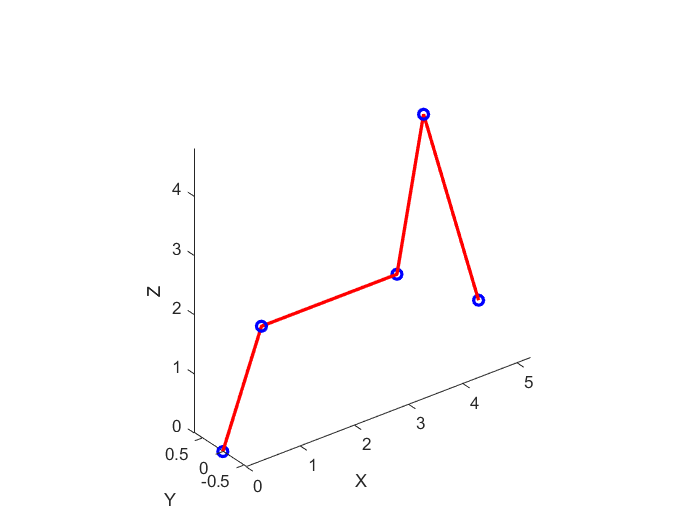

TR4_plot(x,link,'r',1)

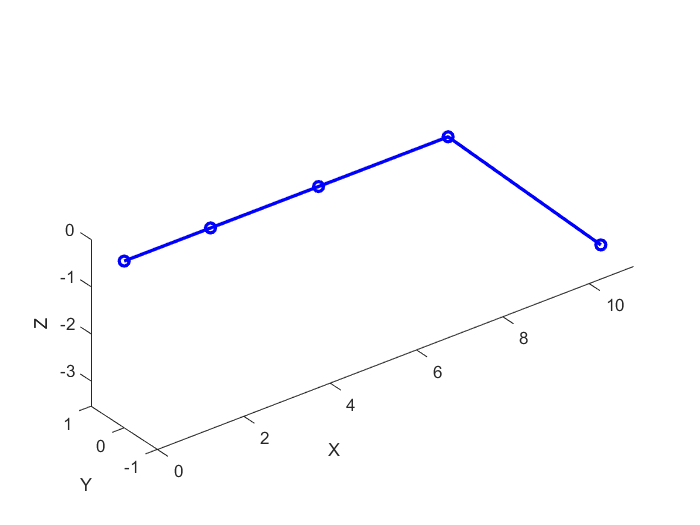

close all
TR4_plot([0 0 0],link,'b',32)